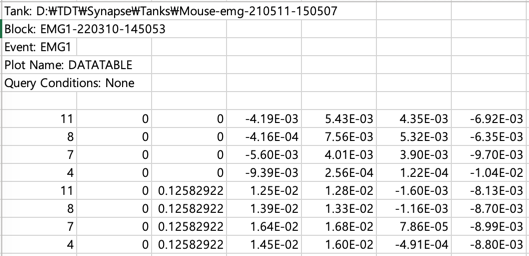

reader = channelReader();

tic 
%                            
reader.readMultiChannelFile( ...
    "./data/height1 - 1,10s - 2x.xlsx", ...#filename
    1, ...#channelColumnIdx
    3, ...#timeColumnIdx
    7, ...#startRowIdx
    4, ...#startColIdx
    nan ... #sample frequency. time column이 있으면 자동으로 frequency 계산하므로 nan을 입력
    ); %일단 파일을 불러옴

This file has 4 channels: 

ans =      4     7     8    11


toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 3.494913초입니다.


%                            organoid, channel, month 


#### 1. 특정 시간 구간의 signal만 사용하기

emg = reader.readSingleChannelFromFile(1, 8, 1);

sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807

(optional)

20-200hz 구간만 남기고 지움(Classification of Five Finger Movement, based on a Low-cost, Real-time EMG System)

emg.bandPass([20,200])


emg.cutTime([10,20]);

new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175


fgfgfg

fgfg

emg.rectify();

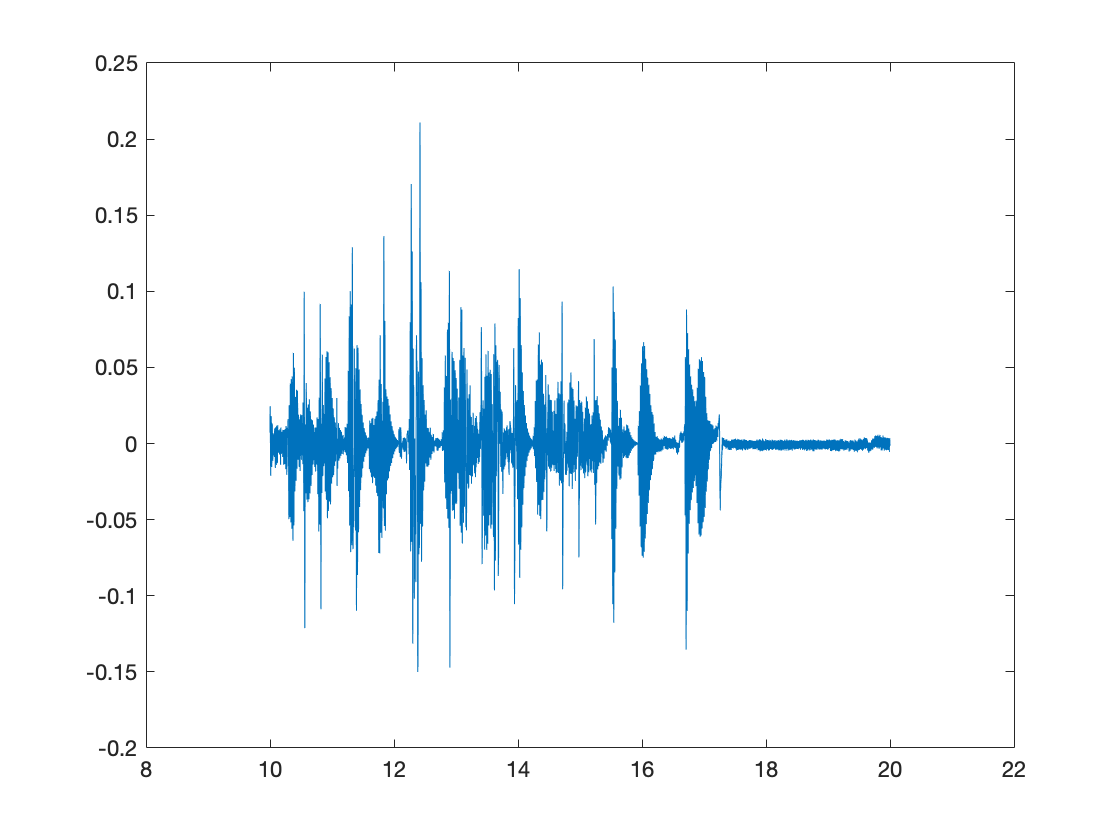

plot(emg.t, emg.raw)

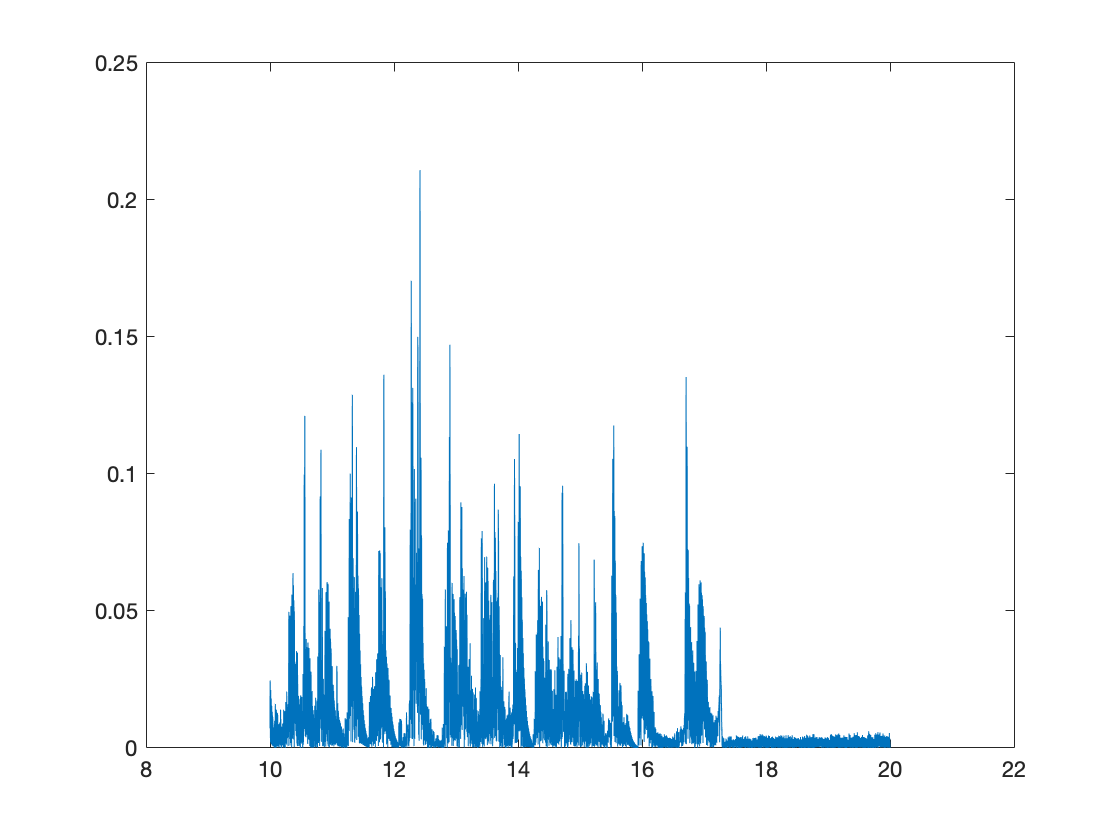

plot(emg.t, emg.signalRawRectified)

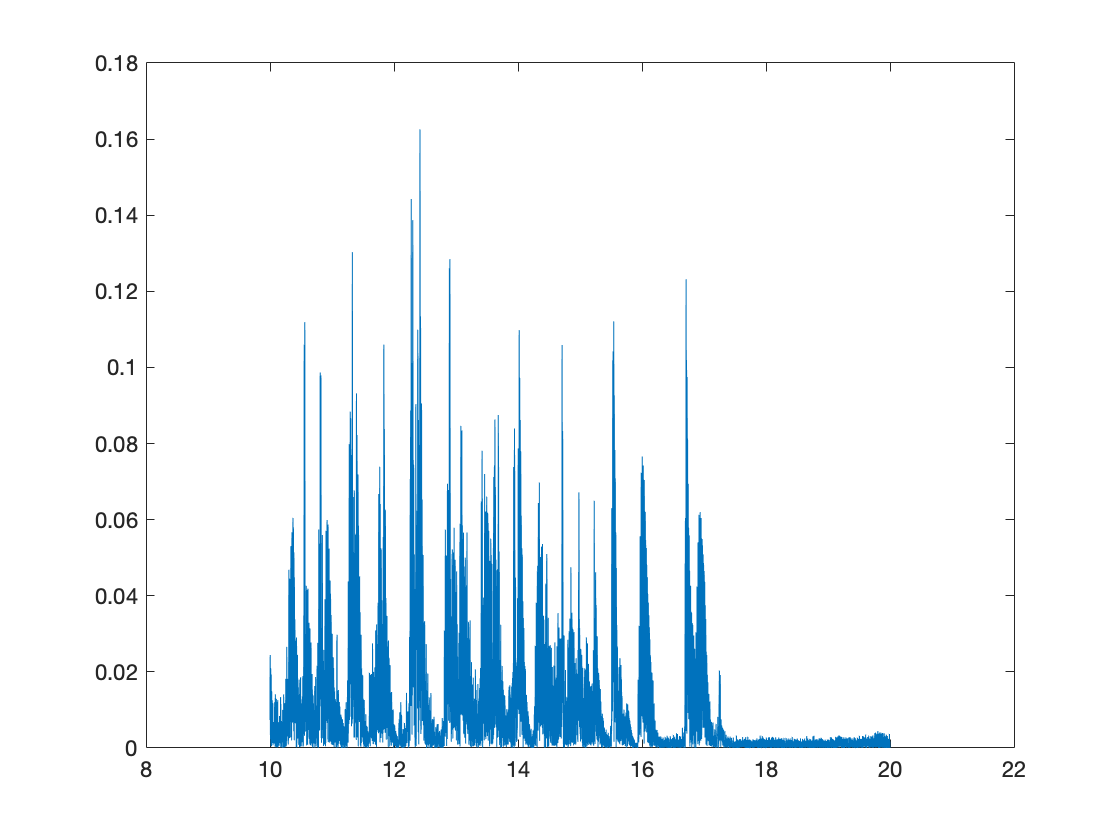

plot(emg.t, emg.signalFilteredRectified)

dfdf

matlab signal processing toolbox 설치 필요

Computes the RMS-envelope, the MA-envelope ot the LE-envelope of an EMG signal.

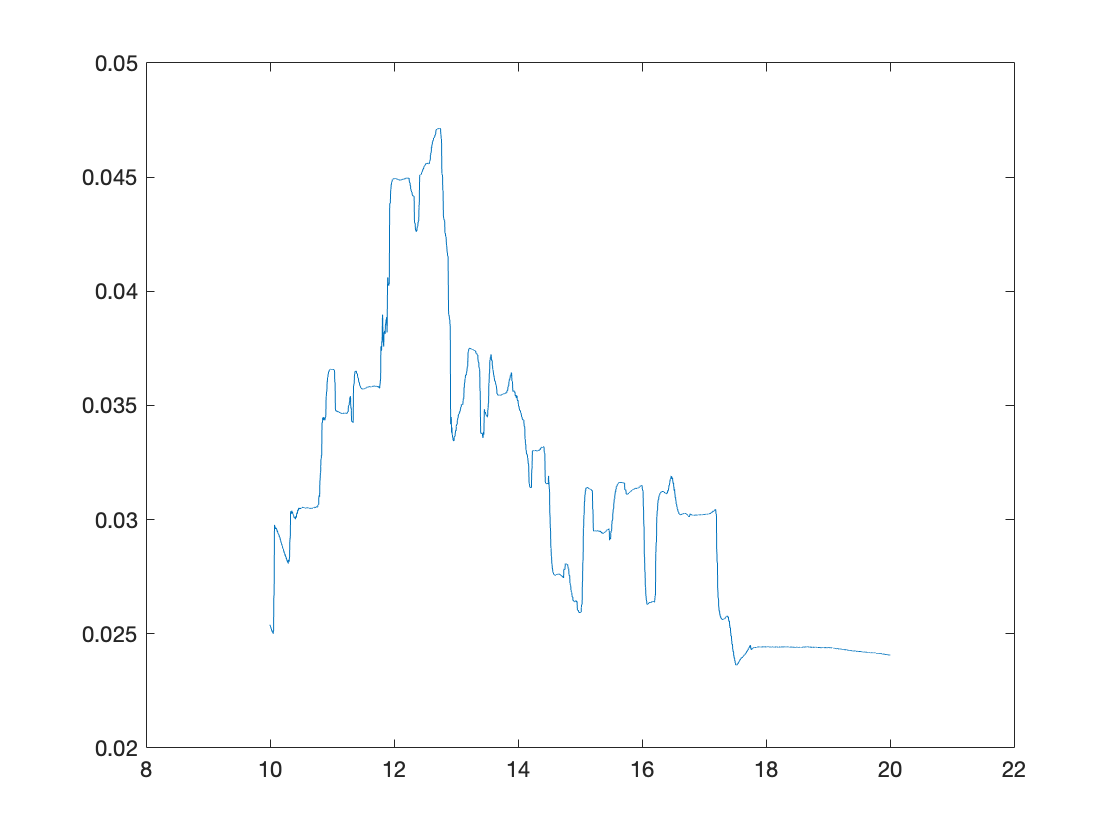

emg.envelope(1000);
plot(emg.t, emg.signalRawEnveloped)

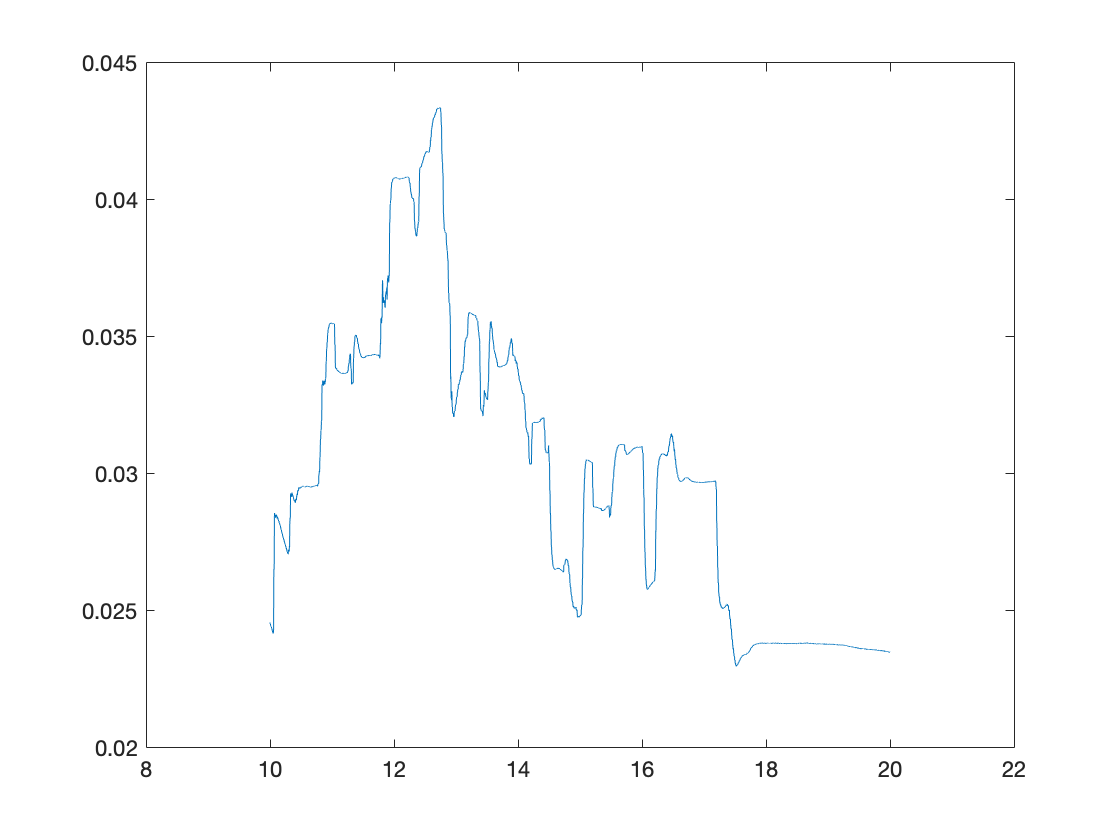

plot(emg.t, emg.signalFilteredEnveloped)

length(emg.signalFilteredEnveloped)

ans = 10175

%                                 organoid, month
pixels = reader.readManyChannelsFromFile(1, 1);

Reading 4 channels at once...

channel number = 4
sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807

channel number = 7
sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807

channel number = 8
sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807

channel number = 11
sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807



pixels =   Map - 속성 있음:

        Count: 4
      KeyType: double
    ValueType: any


pixels.keys

sampling rate가 모두 똑같은 상황을 가정하고 코드를 짰음

%                      nrow, ncol
ani = timeVaryingHeatmapEMG(2,2); % timeVaryingHeatmap 오브젝트 생성. pixel들이 2*2 배열로 되어 있다고 가정.

%  이 pixel의 row번호, column번호, pixel에 mapping할 channel 번호
ani.addPixel(1, 1, pixels(4) );


 In the (1, 1)th slot, added channel 4 


ani.addPixel(1, 2, pixels(7) );


 In the (1, 2)th slot, added channel 7 


ani.addPixel(2, 1, pixels(8) );


 In the (2, 1)th slot, added channel 8 


ani.addPixel(2, 2, pixels(11));


 In the (2, 2)th slot, added channel 11 



ani.cutTime([10,20])


cutting the time of (1, 1)th element = channel 4
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175

cutting the time of (1, 2)th element = channel 7
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175

cutting the time of (2, 1)th element = channel 8
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175

cutting the time of (2, 2)th element = channel 11
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175


ani.rectify()      % 모든 channel에 일괄적으로 rectification 적용
ani.envelope(1000) % 모든 channel에 일괄적으로 rms enveloping 적용 

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 4
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              mea

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 4
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              mea

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 7
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              mea

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 7
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              mea

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 8
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              mea

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 8
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              mea

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 11
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              me

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 11
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 10175
                     startTime: 9.9995
                 endTimeApprox: 20.0009
                durationApprox: 10.0014
                             t: [1×10175 double]
                           raw: [1×10175 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              me

'filtered'은(는) 인식할 수 없는 함수 또는 변수입니다.

오류 발생: timeVaryingHeatmapEMG/envelope (116번 라인)
                    if filtered

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 4
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpik

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 4
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpik

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 7
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpik

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 7
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpik

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 8
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpik

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 8
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpik

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 11
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpi

ch =   channel - 속성 있음:

                   organoidNum: 1
                    channelNum: 11
                         month: 1
                            sf: 1.0173e+03
                       msPerTs: 0.9830
                   nTimestamps: 55807
                     startTime: 0
                 endTimeApprox: 54.8595
                durationApprox: 54.8595
                             t: [1×55807 double]
                           raw: [1×55807 double]
                      filtered: []
             timestampsPrePeak: []
            timestampsPostPeak: []
               spikeTimestamps: []
         spikeTimestampsMatrix: []
                spikeWaveforms: []
                       nSpikes: []
                      PCScores: []
                  explainedVar: []
                      clusters: []
                     nClusters: []
             nSpikesPerCluster: []
          totalMeanSpikeStruct: []
              meanSpi

time interval을 milisecond 단위로 입력